# **Analysis of the Burgers equation by LSUN**

First run TanSacNet/code/setpath

Requirements: MATLAB R2022b 

Contact address: Shogo MURAMATSU, Faculty of Engineering, Niigata University, 8050 2-no-cho Ikarashi, Nishi-ku, Niigata, 950-2181, JAPAN http://msiplab.eng.niigata-u.ac.jp  

Copyright (c) 2023, Hayato Obara and Shogo MURAMATSU, All rights reserved.

clc, clear
close all

% Data folder
datafolder = "../../../data/";


Parameters

% LSUN train
numEpochs = 600;
nCoefs = 4; 
pt = 2;
stride = 2*pt; % Stride (even)

nu = 0.05;
% td-DMD
nDelay = 1;

## Input data

filenameinput = "burgerseq";
if exist(datafolder+filenameinput+"nu_"+replace(num2str(nu),'.','_')+".mat","file")~=2
    main_burgerseq_gen(datafolder+filenameinput,nu)
else
    disp("Data found!")
end

Data found!


Sload = load(datafolder+filenameinput+"nu_"+replace(num2str(nu),'.','_'),"T","X","DataT","dt","dx");
T = Sload.T;
X = Sload.X;
dt = Sload.dt;
dx = Sload.dx;
DataT = Sload.DataT;

## **Data visualisation**

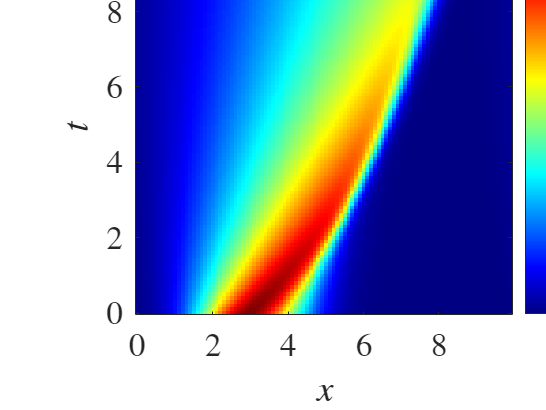

figure
ax = disp_imagesc_(T,X,DataT," $z(x,t)$ of Burgers' equation");
exportgraphics(ax,'fig03a.png')

## LSUN training

-- Settings --
Data size (space): 100
Data size (time): 100
Block size: 4
Output dimension (per block): 4
Number of overlapping blocks: 3

Angles in Lv1_Cmp1_V0 are set to N(0,1e-18)
Angles in Lv1_Cmp1_Qx1rb are set to N(-pi/2,1e-18)
Angles in Lv1_Cmp1_Vx1 are set to N(0,1e-18)
Angles in Lv1_Cmp1_Qx2lt are set to N(-pi/2,1e-18)
Angles in Lv1_Cmp1_Vx2 are set to N(0,1e-18)
Copy angles from Lv1_Cmp1_V0 to Lv1_Cmp1_V0~
Copy angles from Lv1_Cmp1_Vx1 to Lv1_Cmp1_Vx1~
Copy angles from Lv1_Cmp1_Vx2 to Lv1_Cmp1_Vx2~
Copy angles from Lv1_Cmp1_Qx1rb to Lv1_Cmp1_Qx1rb~
Copy angles from Lv1_Cmp1_Qx2lt to Lv1_Cmp1_Qx2lt~
    "MSE: 3.6104e-30"



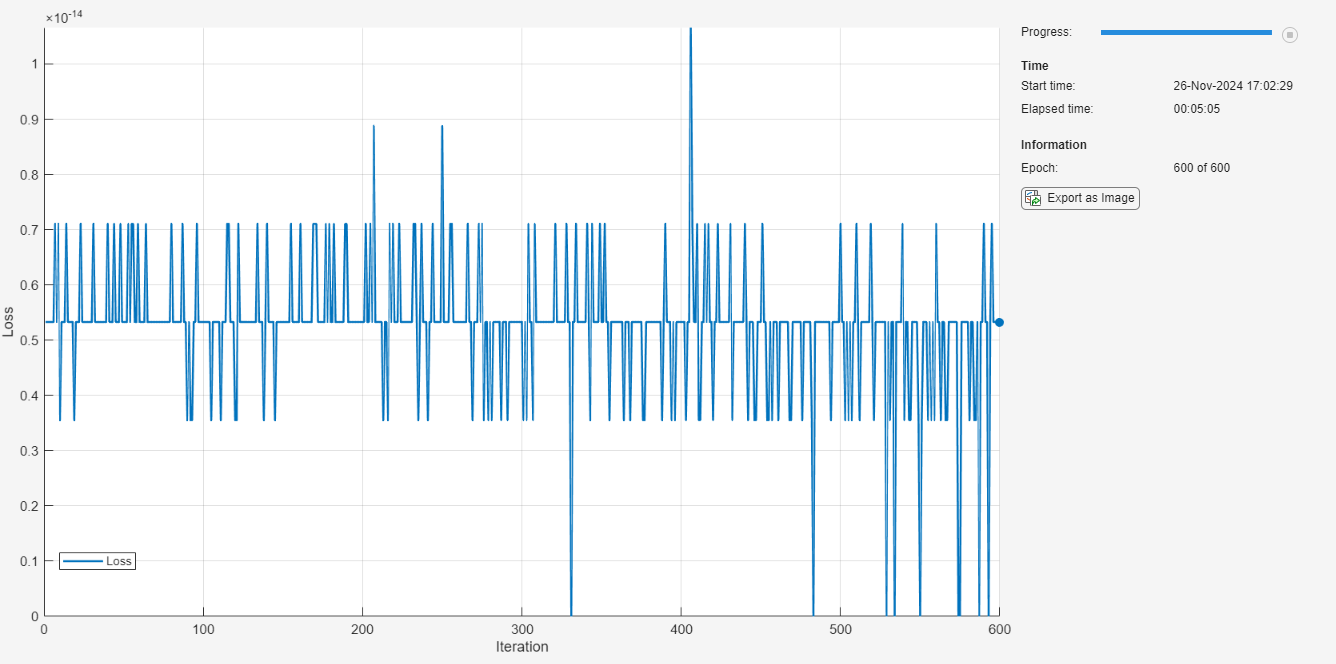

Copy angles from Lv1_Cmp1_V0 to Lv1_Cmp1_V0~
Copy angles from Lv1_Cmp1_Vx1 to Lv1_Cmp1_Vx1~
Copy angles from Lv1_Cmp1_Vx2 to Lv1_Cmp1_Vx2~
Copy angles from Lv1_Cmp1_Qx1rb to Lv1_Cmp1_Qx1rb~
Copy angles from Lv1_Cmp1_Qx2lt to Lv1_Cmp1_Qx2lt~
Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vx1~ to Lv1_Cmp1_Vx1
Copy angles from Lv1_Cmp1_Vx2~ to Lv1_Cmp1_Vx2
Copy angles from Lv1_Cmp1_Qx1rb~ to Lv1_Cmp1_Qx1rb
Copy angles from Lv1_Cmp1_Qx2lt~ to Lv1_Cmp1_Qx2lt


datatype = 'double';
nX = size(DataT,2);
filenamelsun = datafolder + "lsunnet_nX"+num2str(nX)+"_stride" + num2str(stride)+"_nCoefs"+num2str(nCoefs) + "_numEpochs" + num2str(numEpochs);
%if exist(filenamelsun+".mat","file")~=2
    [analsunnet, synlsunnet,coefMask] = fcn_lsun_train(DataT,stride,nCoefs,numEpochs,datatype);

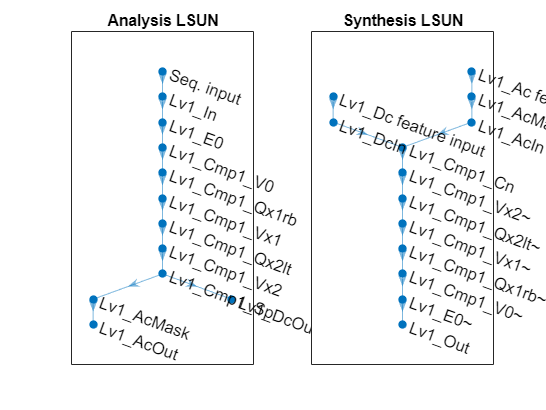

    save(filenamelsun,"analsunnet","synlsunnet","nX","stride","nCoefs","numEpochs","coefMask");
%else
%    disp("LSUN found!")
%end
Slsun = load(filenamelsun,"analsunnet","synlsunnet","nX","stride","nCoefs","coefMask");
analsunnet = Slsun.analsunnet;
synlsunnet = Slsun.synlsunnet;
coefMask = Slsun.coefMask;
stride = Slsun.stride;
nCoefs = Slsun.nCoefs;


figure
subplot(1,2,1)
plot(analsunnet)
title('Analysis LSUN')
subplot(1,2,2)
plot(synlsunnet)
title('Synthesis LSUN')

### Analysis process

nT = size(DataT,1);
ndim = nX

ndim = 100

analsunseq = zeros(nT,stride,ndim/stride,'like',DataT);
for iT = 1:nT
    [dc,ac] = analsunnet.predict(gpuArray(DataT(iT,:))); % dc: 1 x Pos., ac: Ch. x 1 x Pos
    analsunseq(iT,:,:) = cat(2,permute(dc,[3 1 2]),permute(ac,[2 1 3]));
end
% 3-D array w/ Time x Ch. x Pos.
size(analsunseq)

ans =    100     4    25


### Synthesis process

synlsunnet.Layers(11).InputSize

ans =      3     1    25


synlsunnet.Layers(12).InputSize

ans =      1     1    25


synlsunseq = analsunseq;
DataTaprx = zeros(size(DataT),'like',DataT);
for iT = 1:nT
    ac = permute(synlsunseq(iT,2:end,:),[2 1 3]);   
    dc = synlsunseq(iT,1,:);
    DataTaprx(iT,:) = synlsunnet.predict(ac,dc);    
end

### td-DMD


nRange = size(analsunseq,1); 

size(analsunseq) % K x Ch. x Pos.

ans =    100     4    25


matS = eye(stride);
matS = matS(coefMask==1,:)

matS =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


dataY = pagemtimes(matS, permute(analsunseq,[2 1 3])); % Ch. x K x Pos.
dataX = reshape(ipermute(dataY,[2 1 3]),nRange,[]) % K x (Ch.Pos.)

dataX =     0.0362    0.0013   -0.0113   -0.0009    0.1040    0.0026   -0.0280   -0.0021    0.2545    0.0040   -0.0576   -0.0042    0.5299    0.0045   -0.0965   -0.0068    0.9390    0.0024   -0.1293   -0.0090    1.4164   -0.0023   -0.1314   -0.0090    1.8184   -0.0076   -0.0865   -0.0059    1.9869   -0.0101   -0.0045   -0.0003    1.8479   -0.0080    0.0796    0.0054    1.4628   -0.0028    0.1291    0.0089    0.9856    0.0021    0.1313    0.0091    0.5652    0.0044    0.1005    0.0071    0.2758    0.0041
    0.0358    0.0003   -0.0131   -0.0012    0.1051    0.0025   -0.0278   -0.0021    0.2516    0.0037   -0.0553   -0.0040    0.5116    0.0039   -0.0900   -0.0064    0.8899    0.0023   -0.1191   -0.0083    1.3354   -0.0012   -0.1253   -0.0087    1.7396   -0.0057   -0.0948   -0.0065    1.9637   -0.0094   -0.0258   -0.0017    1.8984   -0.0096    0.0623    0.0043    1.5458   -0.0046    0.1285    0.0088    1.0500    0.0017    0.1405    0.0097    0.5977    0.0049    0.1081    0.0076    0.2885 

% Construction of Hankel matrix
x = dataX;

ts = [];
H = [];
%nRange = size(x,1)-1;
nRange = size(x,1);
for k = 0:nRange-nDelay-1
    xkT = [];
    for iDelay = 0:nDelay
        xkT = cat(2,xkT,x(k+iDelay+1,:));
    end
    H = cat(2,H,xkT.');
end
H

H =     0.0362    0.0358    0.0363    0.0370    0.0378    0.0386    0.0395    0.0403    0.0412    0.0420    0.0428    0.0437    0.0444    0.0452    0.0460    0.0467    0.0474    0.0481    0.0487    0.0494    0.0500    0.0506    0.0511    0.0517    0.0522    0.0527    0.0532    0.0537    0.0541    0.0546    0.0550    0.0554    0.0558    0.0561    0.0565    0.0568    0.0572    0.0575    0.0578    0.0581    0.0583    0.0586    0.0589    0.0591    0.0593    0.0596    0.0598    0.0600    0.0602    0.0604
    0.0013    0.0003    0.0006    0.0008    0.0009    0.0010    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0

Step 2 SVD of H

[U,Sgm,V] = svd(H,'econ')

U =    -0.0126   -0.0063   -0.0021    0.0028    0.0013    0.0018    0.0012   -0.0013    0.0013   -0.0008   -0.0015   -0.0003   -0.0019    0.0003   -0.0024    0.0010   -0.0030    0.0019   -0.0040    0.0032   -0.0054    0.0049   -0.0073    0.0072    0.0100    0.0105   -0.0138   -0.0150   -0.0190   -0.0211   -0.0261   -0.0293   -0.0354   -0.0396   -0.0463   -0.0505   -0.0560   -0.0567   -0.0598    0.0591   -0.0058    0.0386   -0.0432    0.0551   -0.0483    0.0227   -0.0338    0.0429   -0.0210    0.0229
   -0.0001    0.0001   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0001   -0.0001   -0.0001    0.0000    0.0000   -0.0001    0.0003   -0.0005    0.0008   -0.0012    0.0018   -0.0025    0.0034   -0.0046    0.0061   -0.0080    0.0103    0.0132    0.0168   -0.0210   -0.0262   -0.0325   -0.0399   -0.0486   -0.0589   -0.0706   -0.0839   -0.0980   -0.1119   -0.1243   -0.1311   -0.1380    0.1422   -0.0164    0.0901   -0.1072    0.1351   -0.1218    0.0646   -0.0891    0.1128   -0.0601    0

Sgm =    44.2104         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   19.5154         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

V =    -0.0973    0.1595   -0.1750   -0.1818    0.1873   -0.1927    0.1978    0.2026    0.2065    0.2098   -0.2118    0.2130   -0.2128    0.2119   -0.2095    0.2064   -0.2021    0.1972   -0.1912    0.1847   -0.1775    0.1699   -0.1618    0.1536    0.1449    0.1364   -0.1277   -0.1193   -0.1108   -0.1027   -0.0947   -0.0870   -0.0793   -0.0719   -0.0644   -0.0567   -0.0486   -0.0400   -0.0327    0.0268   -0.0032    0.0127   -0.0144    0.0138   -0.0105    0.0050   -0.0047    0.0046   -0.0022    0.0019
   -0.0985    0.1602   -0.1716   -0.1728    0.1709   -0.1678    0.1625    0.1558    0.1462    0.1350   -0.1207    0.1048   -0.0863    0.0666   -0.0449    0.0227    0.0008   -0.0241    0.0476   -0.0704    0.0926   -0.1133    0.1327   -0.1503   -0.1661   -0.1799    0.1916    0.2012    0.2088    0.2145    0.2182    0.2202    0.2201    0.2181    0.2132    0.2050    0.1917    0.1723    0.1526   -0.1393    0.0265   -0.0657    0.0895   -0.0819    0.0749   -0.0458    0.0422   -0.0403    0.0258   -0

Step 3 PCT

iMode = 1

iMode = 1

ui = reshape(U(:,iMode),size(x,2),[]).'

ui =    -0.0126   -0.0001    0.0024    0.0002   -0.0235   -0.0002    0.0037    0.0003   -0.0397   -0.0002    0.0053    0.0004   -0.0615   -0.0002    0.0068    0.0005   -0.0884   -0.0001    0.0081    0.0006   -0.1191   -0.0001    0.0089    0.0006   -0.1513    0.0000    0.0090    0.0006   -0.1828    0.0001    0.0084    0.0006   -0.2109    0.0002    0.0071    0.0005   -0.2329    0.0003    0.0050    0.0004   -0.2461    0.0004    0.0022    0.0002   -0.2477    0.0004   -0.0013   -0.0001   -0.2366    0.0003
   -0.0126   -0.0001    0.0024    0.0002   -0.0235   -0.0002    0.0037    0.0003   -0.0394   -0.0002    0.0052    0.0004   -0.0607   -0.0002    0.0066    0.0005   -0.0867   -0.0001    0.0078    0.0006   -0.1164   -0.0001    0.0086    0.0006   -0.1478    0.0000    0.0089    0.0006   -0.1790    0.0001    0.0085    0.0006   -0.2075    0.0002    0.0073    0.0005   -0.2306    0.0003    0.0054    0.0004   -0.2450    0.0004    0.0025    0.0002   -0.2479    0.0004   -0.0010   -0.0001   -0.2378    

V0 = V(1:end-1,:);
V1 = V(2:end,:);
dtAplusI = (V1.')*pinv(V0.') 

dtAplusI =     0.9923   -0.0131   -0.0073    0.0104    0.0099    0.0110    0.0113   -0.0119    0.0123   -0.0127   -0.0130   -0.0134   -0.0136   -0.0138   -0.0139   -0.0140   -0.0140   -0.0140   -0.0139   -0.0138   -0.0137   -0.0135   -0.0133   -0.0131    0.0128   -0.0125   -0.0122    0.0119   -0.0116    0.0112   -0.0108    0.0104   -0.0100    0.0096   -0.0092    0.0087   -0.0084    0.0078   -0.0076   -0.0069   -0.0036    0.0050   -0.0057   -0.0096   -0.0045   -0.0042   -0.0064   -0.0056   -0.0027   -0.0043
    0.0207    0.9813   -0.0301    0.0090    0.0167    0.0141    0.0161   -0.0160    0.0170   -0.0172   -0.0179   -0.0181   -0.0185   -0.0187   -0.0189   -0.0190   -0.0191   -0.0191   -0.0190   -0.0188   -0.0187   -0.0184   -0.0182   -0.0178    0.0175   -0.0171   -0.0167    0.0162   -0.0158    0.0153   -0.0147    0.0142   -0.0137    0.0131   -0.0125    0.0119   -0.0115    0.0106   -0.0104   -0.0095   -0.0049    0.0068   -0.0078   -0.0131   -0.0062   -0.0057   -0.0087   -0.0076   -0.00

Step 4 Discover forcinge signal

v0hat = V(1,:).';
vk = v0hat;
dtrk_ = 0;
dtr = [];
for k = 1:nRange-nDelay-1
    % True value
    vkp1 = V(k+1,:).';
    % Forcasted value
    vkp1hat = dtAplusI*vk;
    % Forcing signal
    dtrk_ = vkp1 - vkp1hat;
    % Update
    vk = vkp1;
    dtr = cat(2,dtr,dtrk_);
end

Learnable parameters

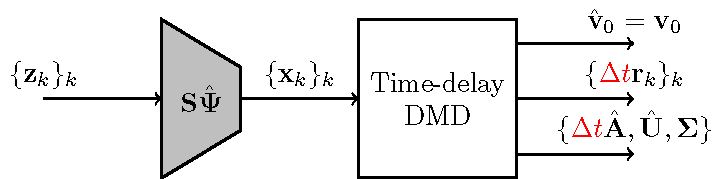

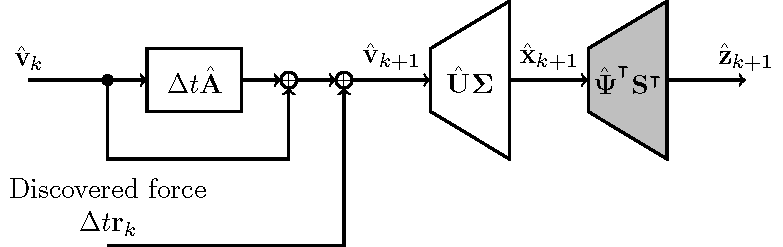

Parameters


$$\hat{\mathbf{v}}_0$$


v0hat

v0hat =    -0.0973
    0.1595
   -0.1750
   -0.1818
    0.1873
   -0.1927
    0.1978
    0.2026
    0.2065
    0.2098



$$\{\Delta t \mathbf{r}_k\}$$


dtr

dtr = 1.0e-15 *

    0.3747   -0.1110    0.0139   -0.0971    0.1388    0.1110   -0.1249   -0.0971   -0.0555   -0.3747   -0.0416    0.0833    0.0694   -0.2776   -0.0278    0.1804    0.0555   -0.2359   -0.1249   -0.0971   -0.3886   -0.0971         0    0.3608   -0.0278    0.0971    0.0416    0.0555    0.0139   -0.1388         0    0.2082    0.1527    0.1804    0.1110    0.1388    0.0971    0.0694    0.0555    0.0971    0.0278    0.1804   -0.0555    0.1249   -0.1665   -0.3053    0.0139   -0.2498    0.1110   -0.1249
   -0.0278   -0.0555    0.7494   -0.1388    0.2776         0    0.0833    0.3331   -0.0833    0.2220    0.2220    0.1943   -0.1388    0.2498   -0.0278   -0.1665    0.1665    0.2776   -0.0971   -0.0416         0    0.2359    0.1110    0.0555   -0.0278    0.2082   -0.0139   -0.1527    0.1318   -0.0833   -0.0278   -0.0694   -0.1596   -0.1318   -0.2359   -0.0278   -0.2984   -0.2932    0.0095   -0.3517   -0.1076   -0.1110    0.0798    0.1076   -0.0659    0.0069   -0.2290   -0.1943  


$$\mathbf{I}+\Delta t \hat{\mathbf{A}}$$


dtAplusI

dtAplusI =     0.9923   -0.0131   -0.0073    0.0104    0.0099    0.0110    0.0113   -0.0119    0.0123   -0.0127   -0.0130   -0.0134   -0.0136   -0.0138   -0.0139   -0.0140   -0.0140   -0.0140   -0.0139   -0.0138   -0.0137   -0.0135   -0.0133   -0.0131    0.0128   -0.0125   -0.0122    0.0119   -0.0116    0.0112   -0.0108    0.0104   -0.0100    0.0096   -0.0092    0.0087   -0.0084    0.0078   -0.0076   -0.0069   -0.0036    0.0050   -0.0057   -0.0096   -0.0045   -0.0042   -0.0064   -0.0056   -0.0027   -0.0043
    0.0207    0.9813   -0.0301    0.0090    0.0167    0.0141    0.0161   -0.0160    0.0170   -0.0172   -0.0179   -0.0181   -0.0185   -0.0187   -0.0189   -0.0190   -0.0191   -0.0191   -0.0190   -0.0188   -0.0187   -0.0184   -0.0182   -0.0178    0.0175   -0.0171   -0.0167    0.0162   -0.0158    0.0153   -0.0147    0.0142   -0.0137    0.0131   -0.0125    0.0119   -0.0115    0.0106   -0.0104   -0.0095   -0.0049    0.0068   -0.0078   -0.0131   -0.0062   -0.0057   -0.0087   -0.0076   -0.00


$$\hat{\mathbf{U}}$$


rRed = nCoefs/stride;
Uhat = U(1:(ndim*rRed),:);
Uhat

Uhat =    -0.0126   -0.0063   -0.0021    0.0028    0.0013    0.0018    0.0012   -0.0013    0.0013   -0.0008   -0.0015   -0.0003   -0.0019    0.0003   -0.0024    0.0010   -0.0030    0.0019   -0.0040    0.0032   -0.0054    0.0049   -0.0073    0.0072    0.0100    0.0105   -0.0138   -0.0150   -0.0190   -0.0211   -0.0261   -0.0293   -0.0354   -0.0396   -0.0463   -0.0505   -0.0560   -0.0567   -0.0598    0.0591   -0.0058    0.0386   -0.0432    0.0551   -0.0483    0.0227   -0.0338    0.0429   -0.0210    0.0229
   -0.0001    0.0001   -0.0000    0.0000   -0.0000    0.0001   -0.0001   -0.0001   -0.0001   -0.0001    0.0000    0.0000   -0.0001    0.0003   -0.0005    0.0008   -0.0012    0.0018   -0.0025    0.0034   -0.0046    0.0061   -0.0080    0.0103    0.0132    0.0168   -0.0210   -0.0262   -0.0325   -0.0399   -0.0486   -0.0589   -0.0706   -0.0839   -0.0980   -0.1119   -0.1243   -0.1311   -0.1380    0.1422   -0.0164    0.0901   -0.1072    0.1351   -0.1218    0.0646   -0.0891    0.1128   -0.0601  


$$\mathbf{\Sigma}$$


Sgm

Sgm =    44.2104         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   19.5154         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Step 5 w/ Discovered forcing signal

vkhat = v0hat;
%dtrk = dtr(:,1);
Xhat = (Uhat*Sgm*vkhat).';
for k = 1:nRange-nDelay-1
    dtrk = dtr(:,k);
    vkp1hat = dtAplusI*vkhat + dtrk;
    Xhat =  cat(1,Xhat,(Uhat*Sgm*vkp1hat).');
    % Update
    vkhat = vkp1hat;
end

% Reshape results
size(Xhat)  % (K-D) x (Ch.Pos.)

ans =     99   100


nRangeOut = nRange - nDelay;
dataYhat = ipermute((reshape(Xhat,nRangeOut,nCoefs,[])),[2 1 3]); % Ch. x (KxPos)
dataXhat = reshape(ipermute(pagemtimes(matS.',dataYhat),[2 1 3]),nRangeOut,stride,[]); % K x Ch. x Pos.
size(dataXhat)

ans =     99     4    25


% Reconstruction of output to be sent through LSUN synthesizer
synlsunseq = dataXhat;
DataHatTaprx = zeros(nRangeOut,size(DataT,2),'like',DataT);
for iT = 1:nRangeOut
    ac = permute(synlsunseq(iT,2:end,:),[2 1 3]);   
    dc = synlsunseq(iT,1,:);
    DataHatTaprx(iT,:) = synlsunnet.predict(ac,dc);    
end

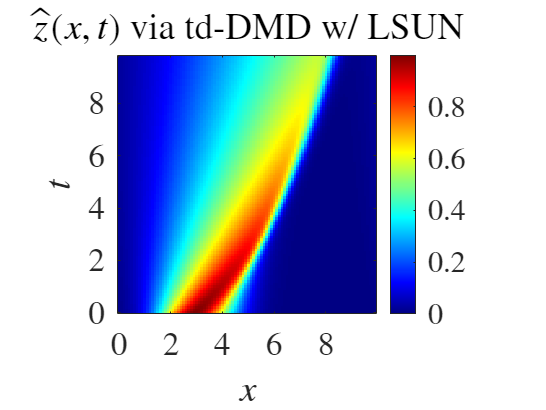

figure
ax = disp_imagesc_(T,X,DataHatTaprx," $\hat{z}(x,t)$ via td-DMD w/ LSUN");
exportgraphics(ax,'fig03c.png')


% MSE評価
mse(DataT(1:nRangeOut,:),DataHatTaprx)

ans = 5.5911e-16

## Discovered forcing signal

r0 = zeros(size(v0hat),'like',v0hat);
%dtrk = dtr(:,1);
Rhat = (Uhat*Sgm*r0).';
for k = 1:nRange-nDelay-1
    dtrk = dtr(:,k);
    rkp1hat = dtrk/dt;
    Rhat =  cat(1,Rhat,(Uhat*Sgm*rkp1hat).');
    % Update
    rkhat = rkp1hat;
end

% Reshape results
size(Rhat)  % (K-D) x (Ch.Pos.)
nRangeOut = nRange - nDelay;
dataYhat = ipermute((reshape(Rhat,nRangeOut,nCoefs,[])),[2 1 3]); % Ch. x (KxPos)
dataQhat = reshape(ipermute(pagemtimes(matS.',dataYhat),[2 1 3]),nRangeOut,stride,[]); % K x Ch. x Pos.
size(dataQhat)


% Reconstruction of output to be sent throughr LSUN synthesizer
synlsunseq = dataQhat;
DataTdfs = zeros(nRangeOut,size(DataT,2),'like',DataT);
for iT = 1:nRangeOut
    ac = permute(synlsunseq(iT,2:end,:),[2 1 3]);   
    dc = synlsunseq(iT,1,:);
    DataTdfs(iT,:) = synlsunnet.predict(ac,dc);    
end


figure
orangered = [255 69 0]/255;
ax = disp_plot3_q_(T(1:size(DataTdfs,1)),X,DataTdfs,orangered);
ax.ZLim = [-3 3]*1e-14;
exportgraphics(ax,'fig04b.png')
disp("||q_k||_2^2/(K-D)")
size(DataTdfs,1)
norm(DataTdfs,'Fro')/size(DataTdfs,1)

Function definition

function ax = disp_plot3_q_(T,X,DataT,c)
if nargin < 4
 c = 'blue';
end

for idx = 1:length(T)
 plot3(X,T(idx)*ones(size(X)),DataT(idx,:),...
 'Color',c,...
 'LineWidth',1)
 hold on
end
xlabel('$n$', 'Interpreter','latex')
ylabel('$k$', 'Interpreter','latex')
zlabel('$[\mathbf{q}_k]_n$', 'Interpreter','latex')
ax = gca;
ax.View = [-30 30];
ax.PlotBoxAspectRatio = [ 2 2 1];
ax.FontSize = 20;
ax.TickLabelInterpreter = 'latex';

grid on
hold off
end


function ax = disp_imagesc_(T,X,DataT,title_)
imagesc(DataT)
colormap("jet")
cb = colorbar;
cb.TickLabelInterpreter = 'latex';
title(title_,'Interpreter','latex')
xlabel('$x$','Interpreter','latex')
ylabel('$t$','Interpreter','latex')
ax = gca;
ax.PlotBoxAspectRatio = [1 1 1];
ax.XTick = 1:20:100;
ax.XTickLabel = round(X(ax.XTick));
ax.YTick = 1:20:100;
ax.YTickLabel = round(T(ax.YTick));
ax.YDir = 'normal';
ax.FontSize = 20;
ax.TickLabelInterpreter = 'latex';
end